# epoch, Id, Var1..Var4

load Data.mat

 

%si prende 1 alla volta tutti e 47 i sensori
for i=1:46 %errore nel sensore 47????
%si prende 1 alla volta le variabili misurate:
%TEMPERATURA - UMIDITA'
    for j=1:4 
        %vai nella seconda colonna, trova quelle che abbiano come
        %valore i e prendi tutta la riga (più righe)
        S{i}=find(Data(:,2)==i); %mi dice quali dati prendere
     
        x{i,j}=Data(S{i},j+2); %mi carica i dati
        %prima prende t, poi u, poi l e, infine, v
        
        detect_x{i,j} = isoutlier(x{i,j}); %ci sono outliers?
        
        x{i,j}= rmoutliers(x{i,j}); %rimuovili
      
        t{i,j}=Data(S{i},1); %prende per ogni sensore gli istanti di tempo
        
        t{i,j}=t{i,j}(~detect_x{i,j}); %toglie gli istanti di tempo
                                       %che hanno gli outliers
       
        [tu{i,j},IA,IC] = unique(t{i,j}); %toglie le ripetizioni
                                          %degli istanti di tempo
        
        xu{i,j}=x{i,j}(IA); %valori senza outliers e ripetizioni

        %     t2=Data(S{2},1);
        %     t2=t2(~detect_x2);
        %     [t2_u,IA,IC] = unique(t2);
        %     x2_u=x2(IA);
       
        %interpolazione dei punti P_n(tempo,valore)
        xint{i,j} = interp1(tu{i,j}, xu{i,j}, [1:10:6e4]);% tu{1,1}
    end
end


% %%
% Indici=[1 2 4];
% Nsens=length(Indici);
%
% for i=1:Nsens
%     subplot(Nsens,4,1+(i-1)*4)
%     plot(Data(S{Indici(i)},1),Data(S{Indici(i)},3))
%     title(['Var1 Sensor number ' num2str(Indici(i))])
%
%     subplot(Nsens,4,2+(i-1)*4)
%     plot(Data(S{Indici(i)},1),Data(S{Indici(i)},4))
%     title(['Var2 Sensor number ' num2str(Indici(i))])
%
%     subplot(Nsens,4,3+(i-1)*4)
%     plot(Data(S{Indici(i)},1),Data(S{Indici(i)},5))
%     title(['Var3 Sensor number ' num2str(Indici(i))])
%
%     subplot(Nsens,4,4+(i-1)*4)
%     plot(Data(S{Indici(i)},1),Data(S{Indici(i)},6))
%     title(['Var4 Sensor number ' num2str(Indici(i))])
% end
% %%
% % figure
% % plot(Data(S{1},1),'*g')
% % hold on
% % plot(Data(S{2},1),'*r')
%
% x1=Data(S{1},3);
% % M=max(x1);
% % for i=1:2000
% %  I=find(x1==M);
% %  %x1(I(2:end))=x1(I(2:end))*0+mean(x1);%x1(I(2:end)-1);
% %  x1(I(2:end))=x1(I(2:end)-1);
% % end
%
% x2=Data(S{2},3);
% % M=max(x2);
% % for i=1:2000
% %  I=find(x2==M);
% %  %x1(I(2:end))=x1(I(2:end))*0+mean(x1);%x1(I(2:end)-1);
% %  x2(I(2:end))=x2(I(2:end)-1);
% % end
% detect_x1 = isoutlier(x1);
% detect_x2 = isoutlier(x2);
% x1= rmoutliers(x1);
% x2= rmoutliers(x2);
%
% t1=Data(S{1},1);
% t1=t1(~detect_x1);
% [t1_u,IA,IC] = unique(t1);
% x1_u=x1(IA);
% t2=Data(S{2},1);
% t2=t2(~detect_x2);
% [t2_u,IA,IC] = unique(t2);
% x2_u=x2(IA);
%
%
% x2_interpolated = interp1(t2_u, x2_u, t1_u);
%
%
% % figure
% % plot(t1_u,x1_u)
% % hold on
% % plot(t2_u,x2_u,'r')
%
% figure
% plot(t1_u,x1_u)
% hold on
% plot(t1_u,x2_interpolated,'r')
%
% figure
% [R,PValue] = corrplot([x1_u x2_interpolated])
%
% %[R,PValue] = corrplot(Sensor_1)

%grafico con correlazioni
%esempio:
%VARIABILE: UMIDITA'
%SENSORI: 1,2,3,4
%figure, corrplot([xint{1,1}' xint{2,1}' xint{3,1}' xint{4,1}'])

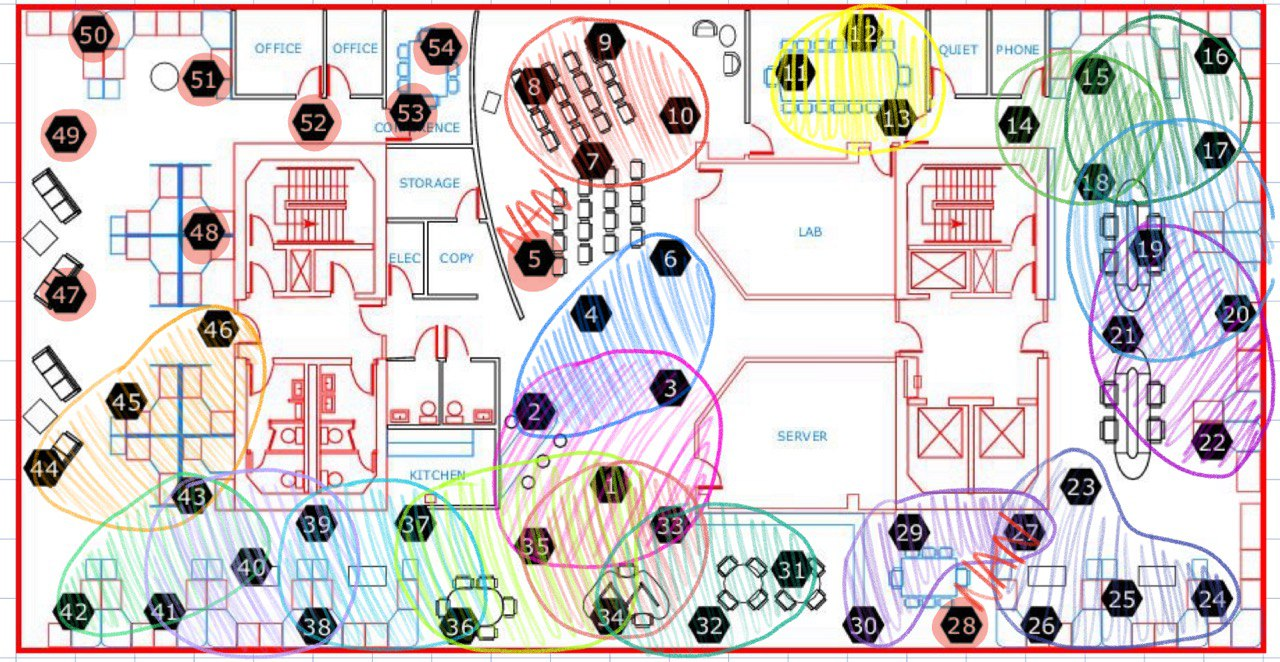

I sensori 5, 28, 47, 48, 49, 50, 51, 52, 53 e 54 sono stati eliminati perché non affidabili.

Prese solo le variabili di umidità e temperatura.

17 zone.

Raggruppamento massimo: 5 sensori.

Raggruppamento minimo: 3 sensori.

Distanza di circa 3 metri da un sensore all'altro.

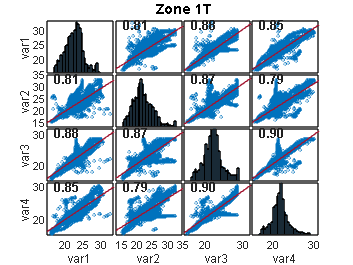

%SENSORI: 43,44,45,46
%TEMPERATURA
figure, corrplot([xint{43,1}' xint{44,1}' xint{45,1}' xint{46,1}'])
title('Zone 1T')

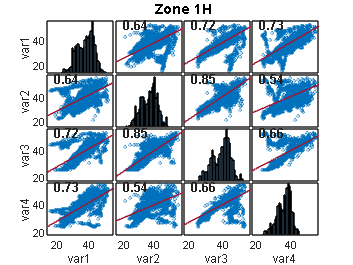

%UMIDITA'
figure, corrplot([xint{43,2}' xint{44,2}' xint{45,2}' xint{46,2}'])
title('Zone 1H')

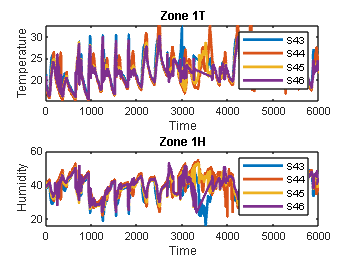


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{43,1}; xint{44,1}; xint{45,1}; xint{46,1}]',LineWidth=2)
title('Zone 1T')
legend('S43','S44','S45','S46')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{43,2}; xint{44,2}; xint{45,2}; xint{46,2}]',LineWidth=2)
title('Zone 1H')
legend('S43','S44','S45','S46')
xlabel('Time')
ylabel('Humidity')

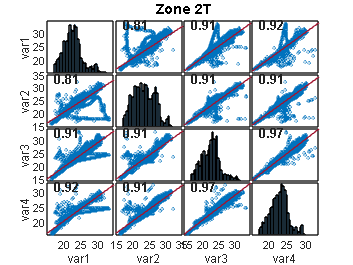

%SENSORI: 40,41,42,43
%TEMPERATURA
figure, corrplot([xint{40,1}' xint{41,1}' xint{42,1}' xint{43,1}'])
title('Zone 2T')

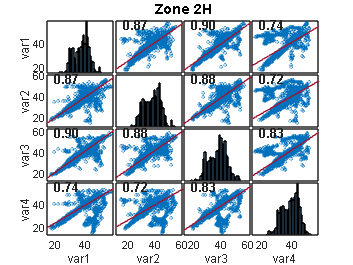

%UMIDITA'
figure, corrplot([xint{40,2}' xint{41,2}' xint{42,2}' xint{43,2}'])
title('Zone 2H')

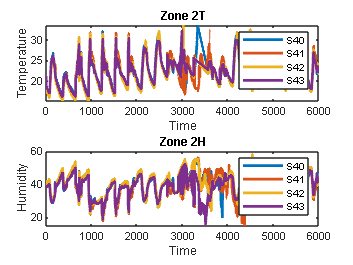


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{40,1}; xint{41,1}; xint{42,1}; xint{43,1}]',LineWidth=2)
title('Zone 2T')
legend('S40','S41','S42','S43')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{40,2}; xint{41,2}; xint{42,2}; xint{43,2}]',LineWidth=2)
title('Zone 2H')
legend('S40','S41','S42','S43')
xlabel('Time')
ylabel('Humidity')

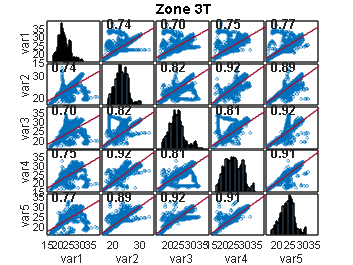

%SENSORI: 38,39,40,41,43
%TEMPERATURA
figure, corrplot([xint{38,1}' xint{39,1}' xint{40,1}' xint{41,1}' xint{43,1}'])
title('Zone 3T')

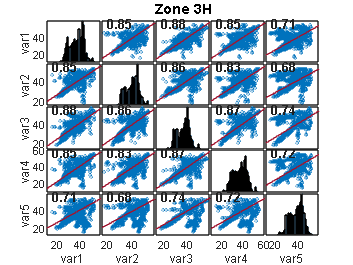

%UMIDITA'
figure, corrplot([xint{38,2}' xint{39,2}' xint{40,2}' xint{41,2}' xint{43,2}'])
title('Zone 3H')

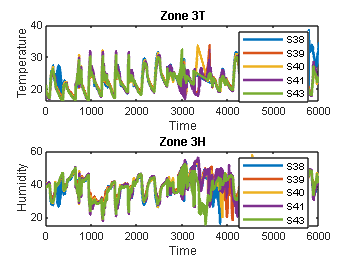


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{38,1}; xint{39,1}; xint{40,1}; xint{41,1}; xint{43,1}]',LineWidth=2)
title('Zone 3T')
legend('S38','S39','S40','S41','S43')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{38,2}; xint{39,2}; xint{40,2}; xint{41,2}; xint{43,2}]',LineWidth=2)
title('Zone 3H')
legend('S38','S39','S40','S41','S43')
xlabel('Time')
ylabel('Humidity')

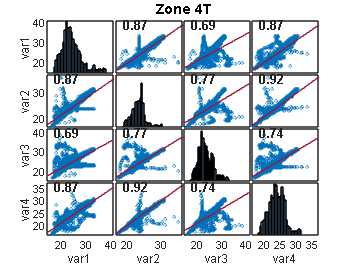

%SENSORI: 36,37,38,39
%TEMPERATURA
figure, corrplot([xint{36,1}' xint{37,1}' xint{38,1}' xint{39,1}'])
title('Zone 4T')

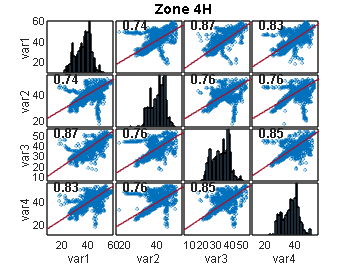

%UMIDITA'
figure, corrplot([xint{36,2}' xint{37,2}' xint{38,2}' xint{39,2}'])
title('Zone 4H')

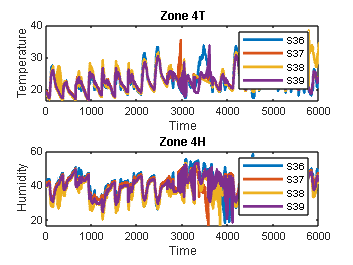


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{36,1}; xint{37,1}; xint{38,1}; xint{39,1}]',LineWidth=2)
title('Zone 4T')
legend('S36','S37','S38','S39')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{36,2}; xint{37,2}; xint{38,2}; xint{39,2}]',LineWidth=2)
title('Zone 4H')
legend('S36','S37','S38','S39')
xlabel('Time')
ylabel('Humidity')

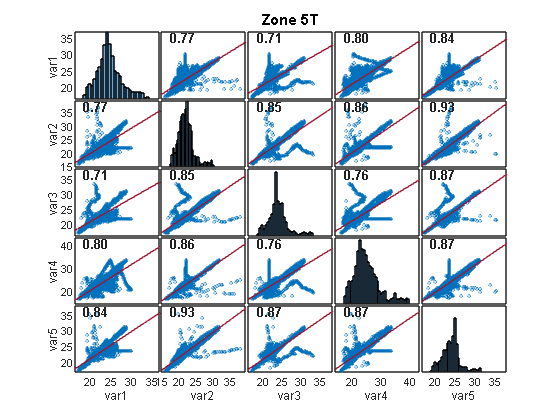

%SENSORI: 1,34,35,36,37
%TEMPERATURA
figure, corrplot([xint{1,1}' xint{34,1}' xint{35,1}' xint{36,1}' xint{37,1}'])
title('Zone 5T')

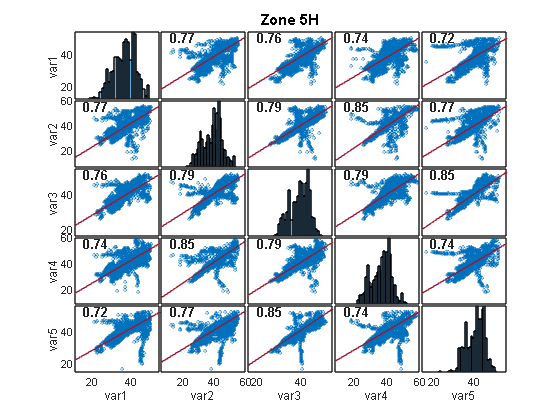

%UMIDITA'
figure, corrplot([xint{1,2}' xint{34,2}' xint{35,2}' xint{36,2}' xint{37,2}'])
title('Zone 5H')

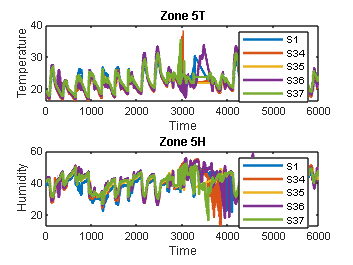


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{1,1}; xint{34,1}; xint{35,1}; xint{36,1}; xint{37,1}]',LineWidth=2)
title('Zone 5T')
legend('S1','S34','S35','S36','S37')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{1,2}; xint{34,2}; xint{35,2}; xint{36,2}; xint{37,2}]',LineWidth=2)
title('Zone 5H')
legend('S1','S34','S35','S36','S37')
xlabel('Time')
ylabel('Humidity')

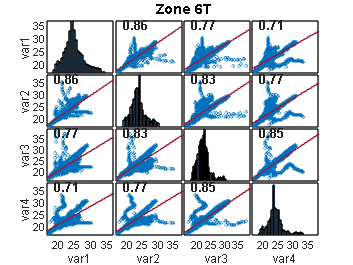

%SENSORI: 1,33,34,35
%TEMPERATURA
figure, corrplot([xint{1,1}' xint{33,1}' xint{34,1}' xint{35,1}'])
title('Zone 6T')

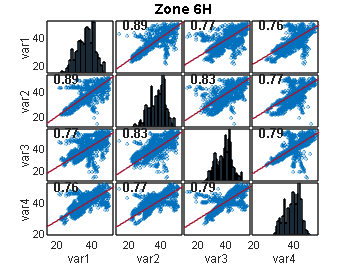

%UMIDITA'
figure, corrplot([xint{1,2}' xint{33,2}' xint{34,2}' xint{35,2}'])
title('Zone 6H')

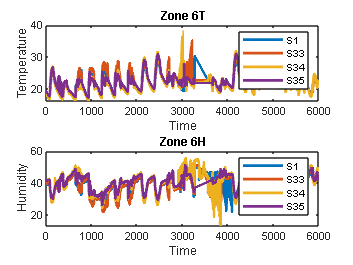


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{1,1}; xint{33,1}; xint{34,1}; xint{35,1}]',LineWidth=2)
title('Zone 6T')
legend('S1','S33','S34','S35')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{1,2}; xint{33,2}; xint{34,2}; xint{35,2}]',LineWidth=2)
title('Zone 6H')
legend('S1','S33','S34','S35')
xlabel('Time')
ylabel('Humidity')

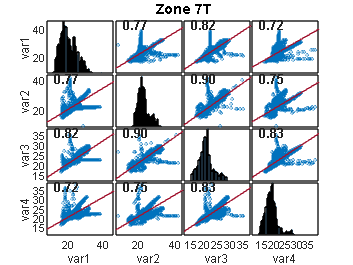

%SENSORI: 31,32,33,34
%TEMPERATURA
figure, corrplot([xint{31,1}' xint{32,1}' xint{33,1}' xint{34,1}'])
title('Zone 7T')

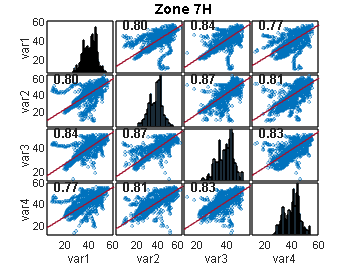

%UMIDITA'
figure, corrplot([xint{31,2}' xint{32,2}' xint{33,2}' xint{34,2}'])
title('Zone 7H')

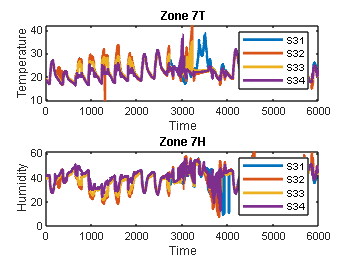


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{31,1}; xint{32,1}; xint{33,1}; xint{34,1}]',LineWidth=2)
title('Zone 7T')
legend('S31','S32','S33','S34')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{31,2}; xint{32,2}; xint{33,2}; xint{34,2}]',LineWidth=2)
title('Zone 7H')
legend('S31','S32','S33','S34')
xlabel('Time')
ylabel('Humidity')

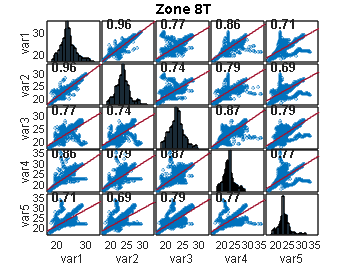

%SENSORI: 1,2,3,33,35
%TEMPERATURA
figure, corrplot([xint{1,1}' xint{2,1}' xint{3,1}' xint{33,1}' xint{35,1}'])
title('Zone 8T')

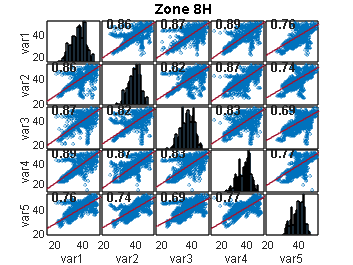

%UMIDITA'
figure, corrplot([xint{1,2}' xint{2,2}' xint{3,2}' xint{33,2}' xint{35,2}'])
title('Zone 8H')

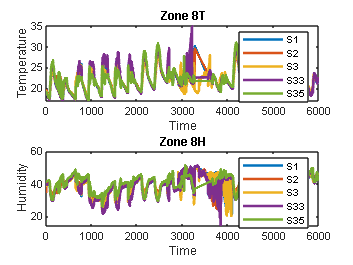


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{1,1}; xint{2,1}; xint{3,1}; xint{33,1}; xint{35,1}]',LineWidth=2)
title('Zone 8T')
legend('S1','S2','S3','S33','S35')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{1,2}; xint{2,2}; xint{3,2}; xint{33,2}; xint{35,2}]',LineWidth=2)
title('Zone 8H')
legend('S1','S2','S3','S33','S35')
xlabel('Time')
ylabel('Humidity')

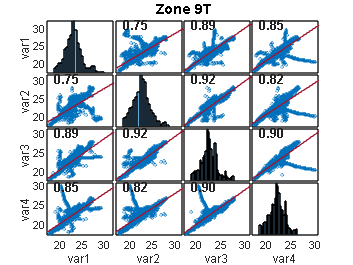

%SENSORI: 2,3,4,6
%TEMPERATURA
figure, corrplot([xint{2,1}' xint{3,1}' xint{4,1}' xint{6,1}'])
title('Zone 9T')

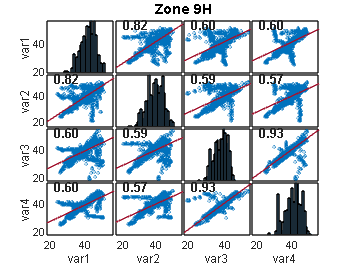

%UMIDITA'
figure, corrplot([xint{2,2}' xint{3,2}' xint{4,2}' xint{6,2}'])
title('Zone 9H')

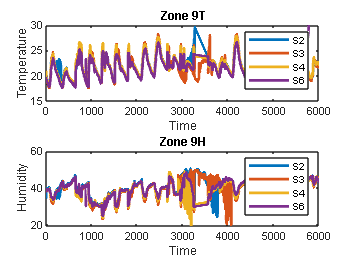


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{2,1}; xint{3,1}; xint{4,1}; xint{6,1}]',LineWidth=2)
title('Zone 9T')
legend('S2','S3','S4','S6')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{2,2}; xint{3,2}; xint{4,2}; xint{6,2}]',LineWidth=2)
title('Zone 9H')
legend('S2','S3','S4','S6')
xlabel('Time')
ylabel('Humidity')

%SENSORI: 7,8,9,10
%TEMPERATURA
figure, corrplot([xint{7,1}' xint{8,1}' xint{9,1}' xint{10,1}'])

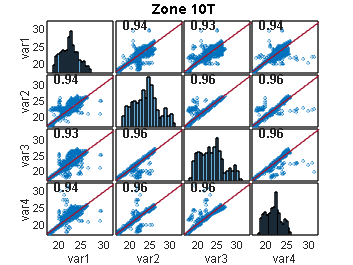

title('Zone 10T')

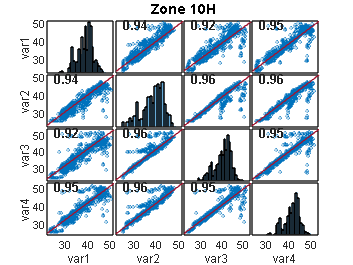

%UMIDITA'
figure, corrplot([xint{7,2}' xint{8,2}' xint{9,2}' xint{10,2}'])
title('Zone 10H')

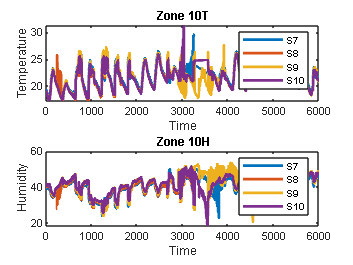


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{7,1}; xint{8,1}; xint{9,1}; xint{10,1}]',LineWidth=2)
title('Zone 10T')
legend('S7','S8','S9','S10')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{7,2}; xint{8,2}; xint{9,2}; xint{10,2}]',LineWidth=2)
title('Zone 10H')
legend('S7','S8','S9','S10')
xlabel('Time')
ylabel('Humidity')

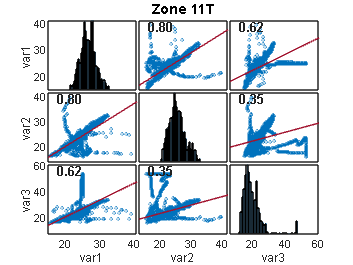

%SENSORI: 27,29,30
%TEMPERATURA
figure, corrplot([xint{27,1}' xint{29,1}' xint{30,1}'])
title('Zone 11T')

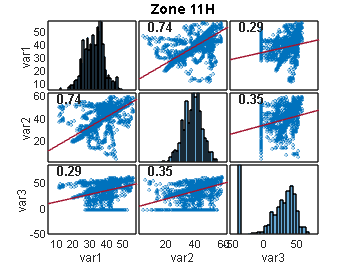

%UMIDITA'
figure, corrplot([xint{27,2}' xint{29,2}' xint{30,2}'])
title('Zone 11H')

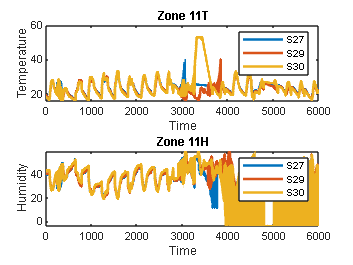


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{27,1}; xint{29,1}; xint{30,1}]',LineWidth=2)
title('Zone 11T')
legend('S27','S29','S30')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{27,2}; xint{29,2}; xint{30,2}]',LineWidth=2)
title('Zone 11H')
legend('S27','S29','S30')
xlabel('Time')
ylabel('Humidity')

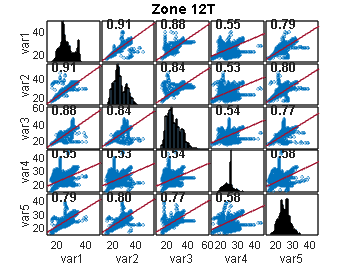

%SENSORI: 23,24,25,26,27
%TEMPERATURA
figure, corrplot([xint{23,1}' xint{24,1}' xint{25,1}' xint{26,1}' xint{27,1}'])
title('Zone 12T')

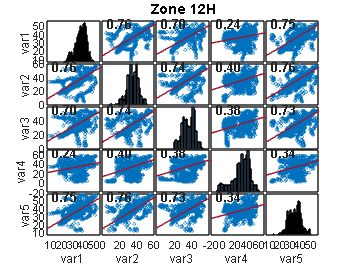

%UMIDITA'
figure, corrplot([xint{23,2}' xint{24,2}' xint{25,2}' xint{26,2}' xint{27,2}'])
title('Zone 12H')

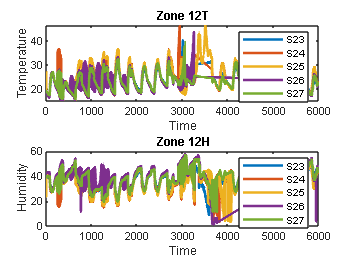


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{23,1}; xint{24,1}; xint{25,1}; xint{26,1}; xint{27,1}]',LineWidth=2)
title('Zone 12T')
legend('S23','S24','S25','S26','S27')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{23,2}; xint{24,2}; xint{25,2}; xint{26,2}; xint{27,2}]',LineWidth=2)
title('Zone 12H')
legend('S23','S24','S25','S26','S27')
xlabel('Time')
ylabel('Humidity')

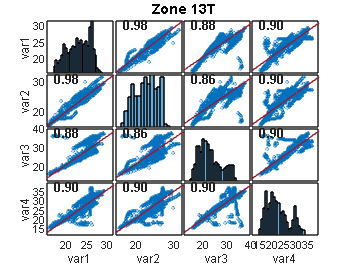

%SENSORI: 19,20,21,22
%TEMPERATURA
figure, corrplot([xint{19,1}' xint{20,1}' xint{21,1}' xint{22,1}'])
title('Zone 13T')

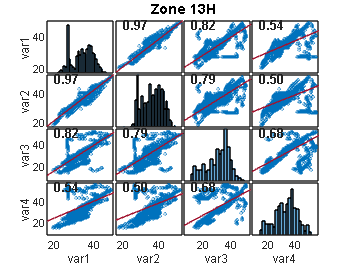

%UMIDITA'
figure, corrplot([xint{19,2}' xint{20,2}' xint{21,2}' xint{22,2}'])
title('Zone 13H')

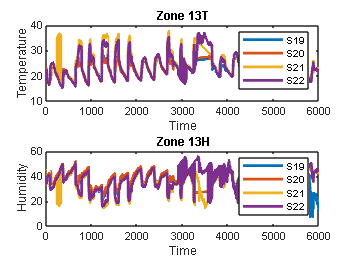


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{19,1}; xint{20,1}; xint{21,1}; xint{22,1}]',LineWidth=2)
title('Zone 13T')
legend('S19','S20','S21','S22')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{19,2}; xint{20,2}; xint{21,2}; xint{22,2}]',LineWidth=2)
title('Zone 13H')
legend('S19','S20','S21','S22')
xlabel('Time')
ylabel('Humidity')

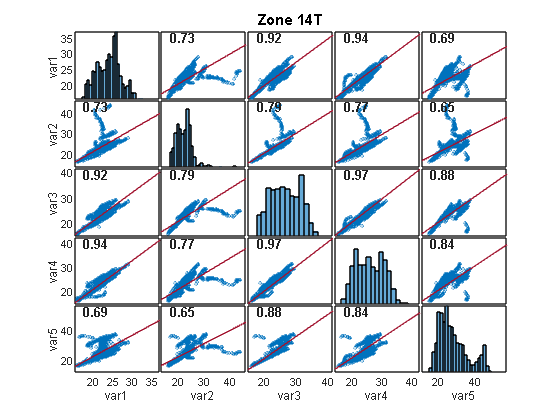

%SENSORI: 17,18,19,20,21
%TEMPERATURA
figure, corrplot([xint{17,1}' xint{18,1}' xint{19,1}' xint{20,1}' xint{21,1}'])
title('Zone 14T')

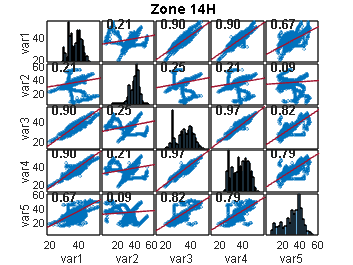

%UMIDITA'
figure, corrplot([xint{17,2}' xint{18,2}' xint{19,2}' xint{20,2}' xint{21,2}'])
title('Zone 14H')

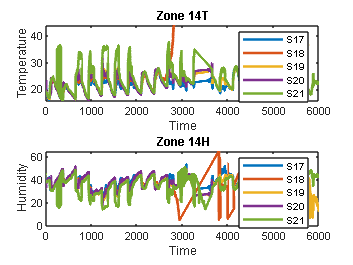


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{17,1}; xint{18,1}; xint{19,1}; xint{20,1}; xint{21,1}]',LineWidth=2)
title('Zone 14T')
legend('S17','S18','S19','S20','S21')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{17,2}; xint{18,2}; xint{19,2}; xint{20,2}; xint{21,2}]',LineWidth=2)
title('Zone 14H')
legend('S17','S18','S19','S20','S21')
xlabel('Time')
ylabel('Humidity')

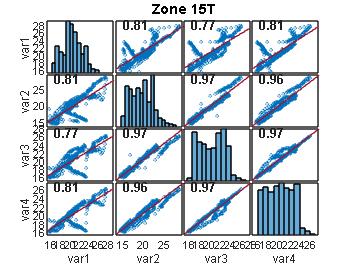

%SENSORI: 15,16,17,18
%TEMPERATURA
figure, corrplot([xint{15,1}' xint{16,1}' xint{17,1}' xint{18,1}'])
title('Zone 15T')

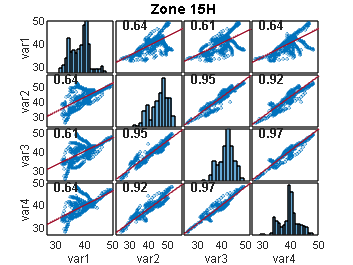

%UMIDITA'
figure, corrplot([xint{15,2}' xint{16,2}' xint{17,2}' xint{18,2}'])
title('Zone 15H')

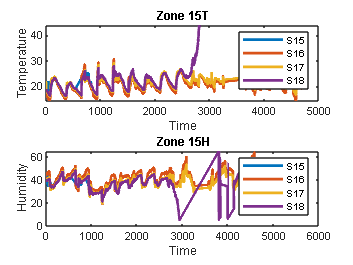


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{15,1}; xint{16,1}; xint{17,1}; xint{18,1}]',LineWidth=2)
title('Zone 15T')
legend('S15','S16','S17','S18')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{15,2}; xint{16,2}; xint{17,2}; xint{18,2}]',LineWidth=2)
title('Zone 15H')
legend('S15','S16','S17','S18')
xlabel('Time')
ylabel('Humidity')

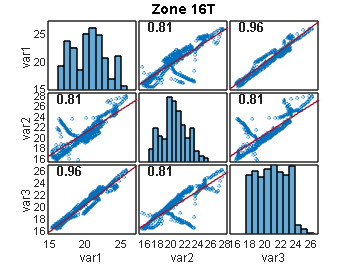

%SENSORI: 14,15,18
%TEMPERATURA
figure, corrplot([xint{14,1}' xint{15,1}' xint{18,1}'])
title('Zone 16T')

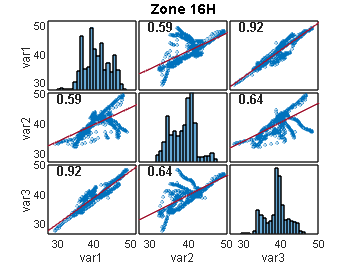

%UMIDITA'
figure, corrplot([xint{14,2}' xint{15,2}' xint{18,2}'])
title('Zone 16H')

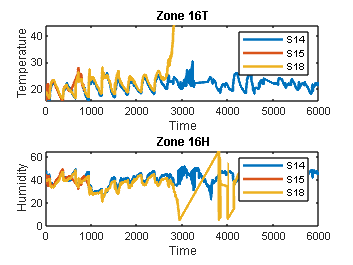


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{14,1}; xint{15,1}; xint{18,1}]',LineWidth=2)
title('Zone 16T')
legend('S14','S15','S18')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{14,2}; xint{15,2}; xint{18,2}]',LineWidth=2)
title('Zone 16H')
legend('S14','S15','S18')
xlabel('Time')
ylabel('Humidity')

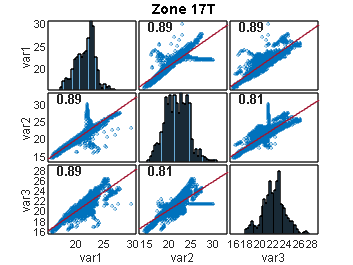

%SENSORI: 11,12,13
%TEMPERATURA
figure, corrplot([xint{11,1}' xint{12,1}' xint{13,1}'])
title('Zone 17T')

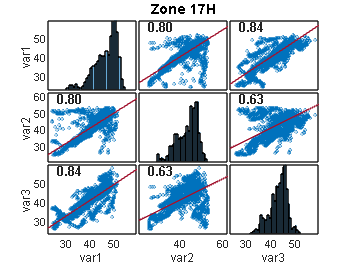

%UMIDITA'
figure, corrplot([xint{11,2}' xint{12,2}' xint{13,2}'])
title('Zone 17H')

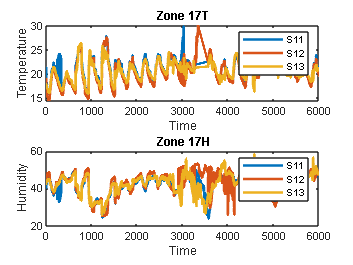


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{11,1}; xint{12,1}; xint{13,1}]',LineWidth=2)
title('Zone 17T')
legend('S11','S12','S13')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{11,2}; xint{12,2}; xint{13,2}]',LineWidth=2)
title('Zone 17H')
legend('S11','S12','S13')
xlabel('Time')
ylabel('Humidity')

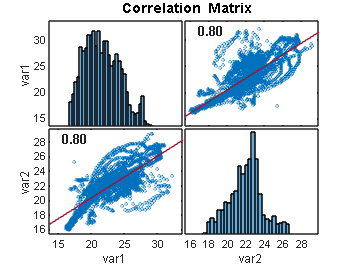

%%%PROVE CON SENSORI MOLTO DISTANTI%%%

%SENSORI: 41,17
%TEMPERATURA
figure, corrplot([xint{41,1}' xint{17,1}'])

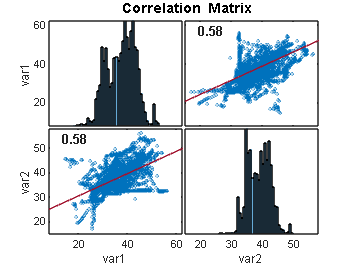

%UMIDITA'
figure, corrplot([xint{41,2}' xint{17,2}'])

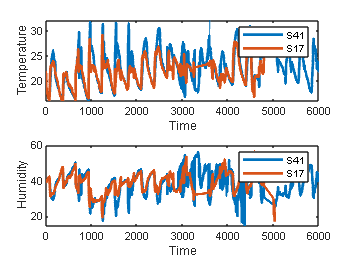


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{41,1}; xint{17,1}]',LineWidth=2)
legend('S41','S17')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{41,2}; xint{17,2}]',LineWidth=2)
legend('S41','S17')
xlabel('Time')
ylabel('Humidity')

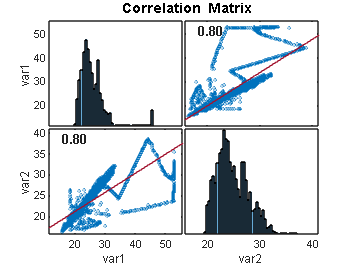

%SENSORI: 30,31
%TEMPERATURA
figure, corrplot([xint{30,1}' xint{31,1}'])

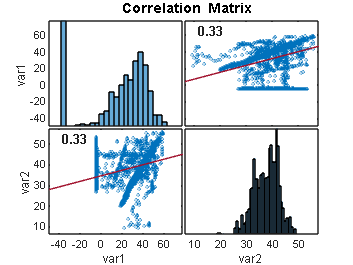

%UMIDITA'
figure, corrplot([xint{30,2}' xint{31,2}'])

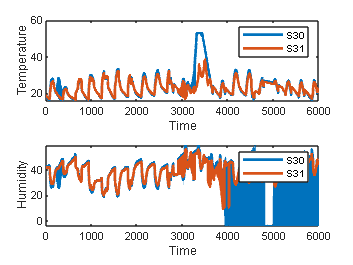


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{30,1}; xint{31,1}]',LineWidth=2)
legend('S30','S31')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{30,2}; xint{31,2}]',LineWidth=2)
legend('S30','S31')
xlabel('Time')
ylabel('Humidity')

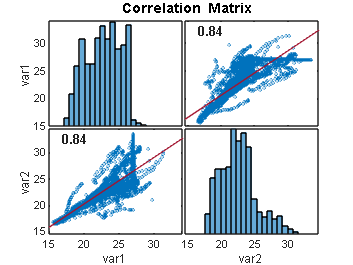

%SENSORI: 20,40
%TEMPERATURA
figure, corrplot([xint{20,1}' xint{40,1}'])

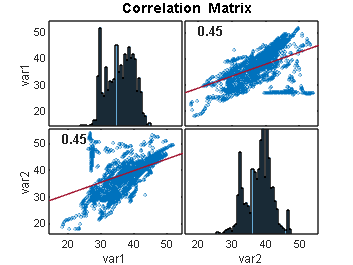

%UMIDITA'
figure, corrplot([xint{20,2}' xint{40,2}'])

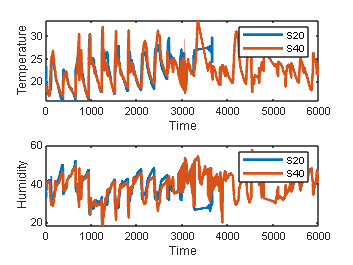


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{20,1}; xint{40,1}]',LineWidth=2)
legend('S20','S40')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{20,2}; xint{40,2}]',LineWidth=2)
legend('S20','S40')
xlabel('Time')
ylabel('Humidity')

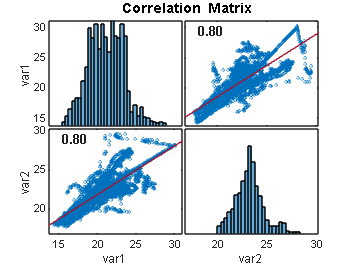

%SENSORI: 12,2
%TEMPERATURA
figure, corrplot([xint{12,1}' xint{2,1}'])

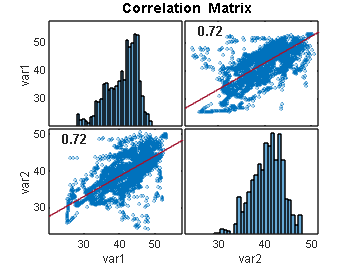

%UMIDITA'
figure, corrplot([xint{12,2}' xint{2,2}'])

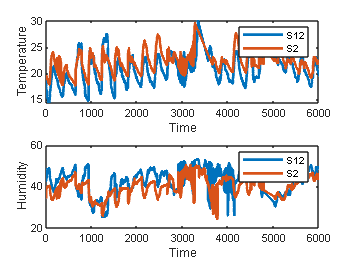


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{12,1}; xint{2,1}]',LineWidth=2)
legend('S12','S2')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{12,2}; xint{2,2}]',LineWidth=2)
legend('S12','S2')
xlabel('Time')
ylabel('Humidity')

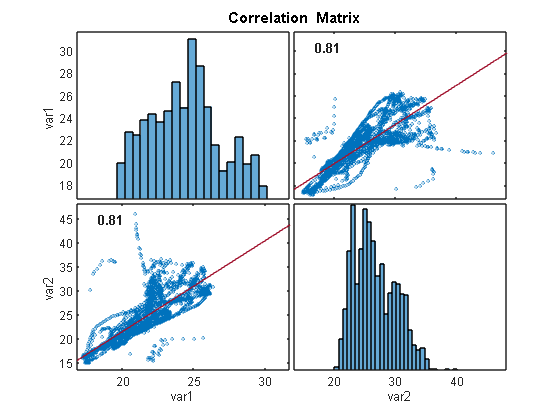

%SENSORI: 8,24
%TEMPERATURA
figure, corrplot([xint{8,1}' xint{24,1}'])

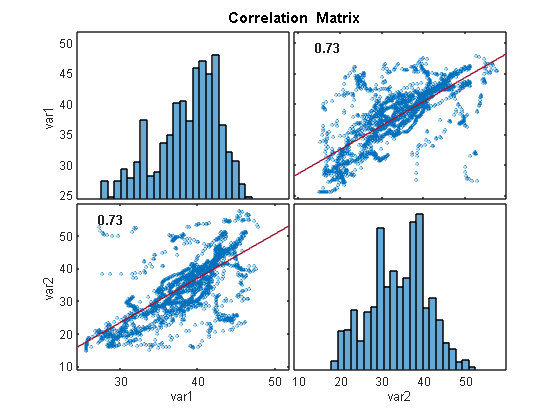

%UMIDITA'
figure, corrplot([xint{8,2}' xint{24,2}'])

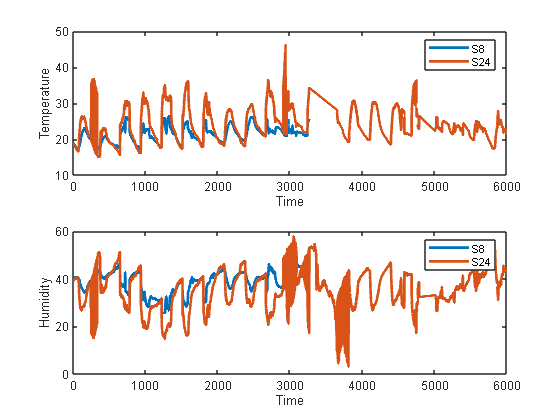


% % % % % % % % %
%TEMPERATURA
figure
subplot(2,1,1)
plot([xint{8,1}; xint{24,1}]',LineWidth=2)
legend('S8','S24')
xlabel('Time')
ylabel('Temperature')
%UMIDITA'
subplot(2,1,2)
plot([xint{8,2}; xint{24,2}]',LineWidth=2)
legend('S8','S24')
xlabel('Time')
ylabel('Humidity')